# 数据可视化 小组Project

钟诚        16307110259

周璐鹿    15307110349

张奕朗    16307130242

清理运行环境

clear
clc
close all

## 局部仿射变换测试

读取测试图片

testImg = imread('../test_images/zc.jpg');
testImg = double(testImg) / 256;

反向仿射变换：将图像中部两个$32\times 32$的矩形分别顺时针、逆时针旋转${45}^{\circ }$

[H,W] = size(testImg,[1,2]);
testTransMap = zeros(H,W);
testTransMap(H/2-31:H/2,W/2-31:W/2) = 1;
testTransMap(H/2+1:H/2+32,W/2+1:W/2+32) = 2;
testTransform = cell(1,2);
testTransform{1} = [1/sqrt(2), 1/sqrt(2), 0 ;
                   -1/sqrt(2), 1/sqrt(2), 0 ;
                       0     ,     0    , 1 ];
testTransform{2} = [1/sqrt(2),-1/sqrt(2), 0 ;
                    1/sqrt(2), 1/sqrt(2), 0 ;
                       0     ,     0    , 1 ];

调用函数，进行测试

                 
%localAffine_inv(testImg,testTransform,testTransMap,'dist_e',2,'visualize',true);

读取原本的图像和待改变的图像，并标记相应的区域

A = imread('../test_images/B.jpg');
A = A(1:545,:,:);
A = double(A) / 256;
left_eyeA = [150, 175, 205, 235];
right_eyeA = [150, 174, 245, 278];
noseA = [175,198,232,245,225,255];
mouthA = [190,220,220,260];

goal = imread('../test_images/dlrb.jpg');
goal = double(goal) / 256;
left_eye_goal = [220, 270, 160, 230];
right_eye_goal = [195, 265, 260, 330];
nose_goal = [270,320,240,260,220,290];
mouth_goal = [330, 365, 210, 295];


计算相关transform矩阵

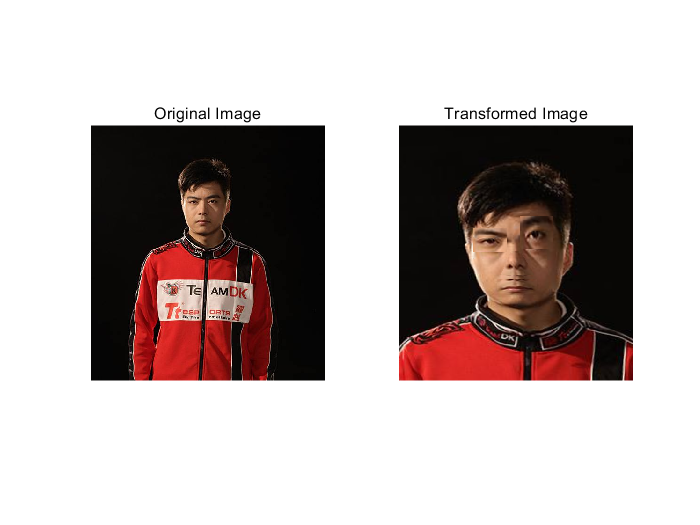

shape_A = size(A);
shape_goal = size(goal);
transMap = form_transMap(shape_goal, left_eye_goal, right_eye_goal, nose_goal, mouth_goal);
transform{1} = form_transform(shape_A, shape_goal, left_eyeA, left_eye_goal);
transform{2} = form_transform(shape_A, shape_goal, right_eyeA, right_eye_goal);
transform{3} = form_transform(shape_A, shape_goal, noseA, nose_goal);
transform{4} = form_transform(shape_A, shape_goal, mouthA, mouth_goal);
localAffine_inv(A,transform,transMap);